%加速阶段
% 列车的质量
m = 176300;
% 列车的牵引力
F1 = 310000;
% 阻力
F3 = @(v) 2089.5+9.8 * v+6* v^2;
% 列车的初始速度
v0 = 0;
% 行驶时间范围
tspan = [0, 13.74];
% 定义微分方程
odefun = @(t, v) (F1 - F3(v)) / m;
% 使用 ode45 求解微分方程
[t, v] = ode45(odefun, tspan, v0)

t =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0003
    0.0004
    0.0005
    0.0007
    0.0014


v =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


% 计算列车行驶的距离
s = cumtrapz(t, v)

s =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


%匀速阶段
vvv=27.777777777

vvv = 27.7778

ttt=17:1:190

ttt =     17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66


sss=222.9230+vvv*(ttt-16)

sss = 1.0e+03 *

    0.2507    0.2785    0.3063    0.3340    0.3618    0.3896    0.4174    0.4451    0.4729    0.5007    0.5285    0.5563    0.5840    0.6118    0.6396    0.6674    0.6951    0.7229    0.7507    0.7785    0.8063    0.8340    0.8618    0.8896    0.9174    0.9451    0.9729    1.0007    1.0285    1.0563    1.0840    1.1118    1.1396    1.1674    1.1951    1.2229    1.2507    1.2785    1.3063    1.3340    1.3618    1.3896    1.4174    1.4451    1.4729    1.5007    1.5285    1.5563    1.5840    1.6118


%减速阶段
ttspan=[0,5.5];
F2=760000;
F4 = @(vv) 2089.5+9.8 * vv+6* vv^2;
vv0=23.8296

vv0 = 23.8296

odefun=@(tt,vv)(-F2-F4(vv))/m

odefun = 包含以下值的 function_handle :
    @(tt,vv)(-F2-F4(vv))/m


[tt,vv]=ode45(odefun,ttspan,vv0)

tt =          0
    0.1375
    0.2750
    0.4125
    0.5500
    0.6875
    0.8250
    0.9625
    1.1000
    1.2375


vv =    23.8296
   23.2325
   22.6355
   22.0386
   21.4418
   20.8452
   20.2487
   19.6523
   19.0561
   18.4599


ss=cumtrapz(tt,vv)

ss =          0
    3.2355
    6.3889
    9.4603
   12.4496
   15.3568
   18.1820
   20.9252
   23.5864
   26.1656


%%
% tsv是加速阶段
% ttt，sss,vvv是匀速阶段
% tt,ss,vv是减速阶段

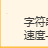

%画图
t1=A(:,1);
v1=A(:,2);
s1=A(:,3);
e1=A(:,5);
plot(s1,v1,'LineWidth',1)
xlabel('距离(m)')
ylabel('速度(m/s)')
title("速度-距离曲线");
grid on;     % 绘制主网格
grid minor;

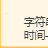

plot(s1,t1,'LineWidth',1)
xlabel('距离(m)')
ylabel('时间(s)')
title("时间-距离曲线");
grid on;     % 绘制主网格
grid minor;

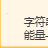

plot(s1,e1,'LineWidth',1)
xlabel('距离(m)')
ylabel('能量(J)')
title("能量-距离曲线");
grid on;     % 绘制主网格
grid minor;